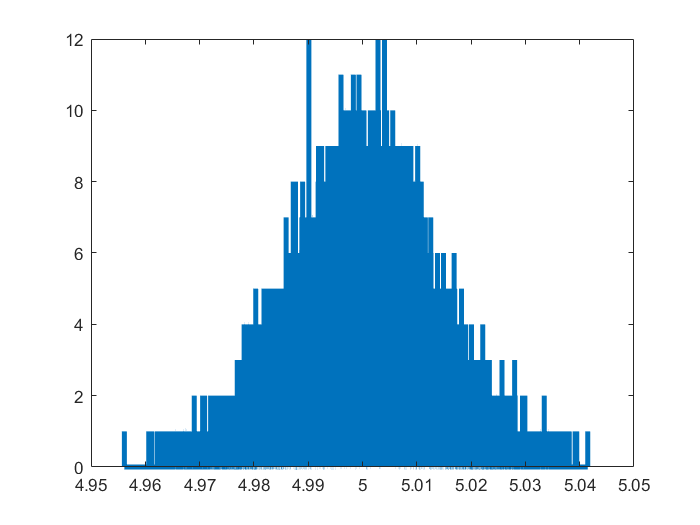

d = random('Normal', 5., 0.01, [1,100000]);
histogram(d,100000,'DisplayStyle',"stairs",'LineWidth',3)
xlim([4.95,5.05])


% 1B: for a given z value, returns the associated probability of the
% Gaussian 
n = normcdf(-1.6) % returns the appropriate probability associated with z = -1.6

n = 0.0548

n = normcdf(0) % returns the appropriate probability associated with z = 0

n = 0.5000

n = normcdf(1.6) % returns the appropriate probability associated with z = 1.6

n = 0.9452

n = 1-normcdf(5) % Complimentary value calculated to avoid rounding error

n = 2.8665e-07


% 1C
% Outputs z value associated with the standard normal probability input. Z
% values are checked against a z-table for validity
norminv(.8413) %approximately a sigma value of 1

ans = 0.9998

norminv(0.9772) %approximately a sigma value of 2

ans = 1.9991

n5 = normcdf(5)

n5 = 1.0000

norminv(n5) %approximately a sigma value of 5

ans = 5.0000

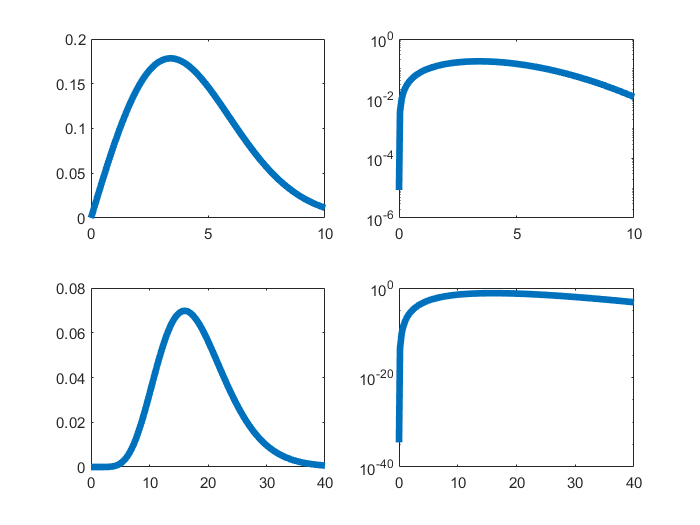


%1D The minus sign that appears indicates that the probability is to the
%left of the mean. 

%2
x = linspace(0,10,100000);
rayl = makedist("Rayleigh",'b',3.4);

subplot(2,2,2)
plot(x,pdf(rayl,x),"LineWidth",4);
set(gca,'YScale','log')

subplot(2,2,1)
plot(x,pdf(rayl,x),"LineWidth",4);

x = linspace(0,40,100000);    
chisq = makedist("Gamma",'a',18/2.,'b',2.); %special case for Chi-squared
subplot(2,2,4)
plot(x,pdf(chisq,x),"LineWidth",4);
set(gca,'YScale','log')
subplot(2,2,3)
plot(x,pdf(chisq,x),"LineWidth",4);


%3A Rayleigh distribution, value of 9.95
%3B Question - If there is no signal, and the signal-free data has a
%Rayleighan distribution, what is the probability that the data produced a
%signal that is equally or more signal-like than I observed?
%3C Integral of the probability distribution function of the Rayleighan
%distribution from 9.95 to infinity. 
y = cdf(rayl,9.95)

y = 0.9862

%P(r) = (r*e^((-r^2)/(2*s^2)))/(s^2)